# **demo01 of writeMesh**

**Triangular mesh with single phase**

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/writeMesh).

## Initialize

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Load mesh

Let's load the mesh data from "mesh_data_1.mat"

load("mesh_data_1.mat")

We will see 2 variables.

vert

vert =    44.5000   48.5000
   52.5000   98.5000
   76.5000  158.5000
   84.5000   96.5000
  100.5000  156.5000
  104.5000   17.5000
  104.5000   47.5000
  105.5000  205.5000
  105.5000  222.5000
  109.5000  214.5000


ele

ele =     36    17    86
    49    77    58
    77    84    88
    57    82    92
    45    71    22
     4    73    40
    87    67    66
    52    28    46
    86    35    36
     5    82    64


## Plot mesh

Use function plotMeshes to plot mesh.

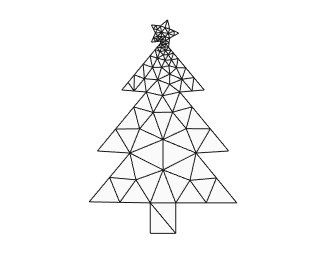

plotMeshes(vert,ele);

## Export as inp file (Abaqus)

We use function printInp2d to write 2d mesh to inp file.

The exported inp file would have a model with one part, which contains one section.

We can specify element type, precision_nodecoor and file name.

ele_type = 'CPS3';
precision_nodecoor = 8;
file_name = 'test.inp';

printInp2d( vert, ele, [], ele_type, precision_nodecoor, file_name );

printInp2d Done! Check the inp file!


## Export as bdf file (Nastran bulk data)

We use function printBdf2d to write 2d mesh to bdf file.

precision_nodecoor = 8;
file_name = 'test.bdf';

printBdf2d( vert, ele, [], [], precision_nodecoor, file_name );

printBdf2d Done! Check the bdf file!


## Export as msh file (Gmsh mesh file)

We use function printMsh to write 2d mesh to msh file.

precision_nodecoor = 8;
file_name = 'test.msh';

printMsh( vert, ele, [], [], precision_nodecoor, file_name );

printMsh Done! Check the msh file!


When we open 'test.msh' in Gmsh, we can see 1 physical surface, which corresponds to 1 phase in our mesh.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo